
$$G(s)=\frac{\omega_0}{s + \omega_0} \\
\omega_i<\omega_0, \text{keep amplitude}  \\
\omega_i>\omega_0, \text{shrink amplitude}$$


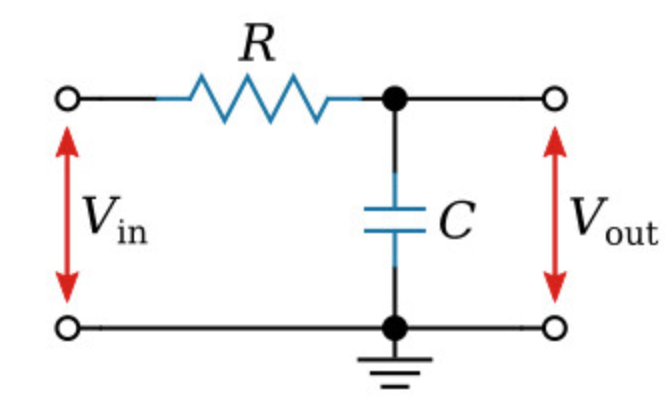


$$G(s)=V_{out}/V_{in}=\frac{1}{1+RCs}=\frac{\frac{1}{RC}}{s+\frac{1}{RC}}$$



$$T=RC, \text{time constant}$$



$$\omega_0=\frac{1}{RC} rad/s$$



$$fc=\frac{\omega_0}{2\pi}=\frac{1}{2\pi RC} Hz$$


state-space form

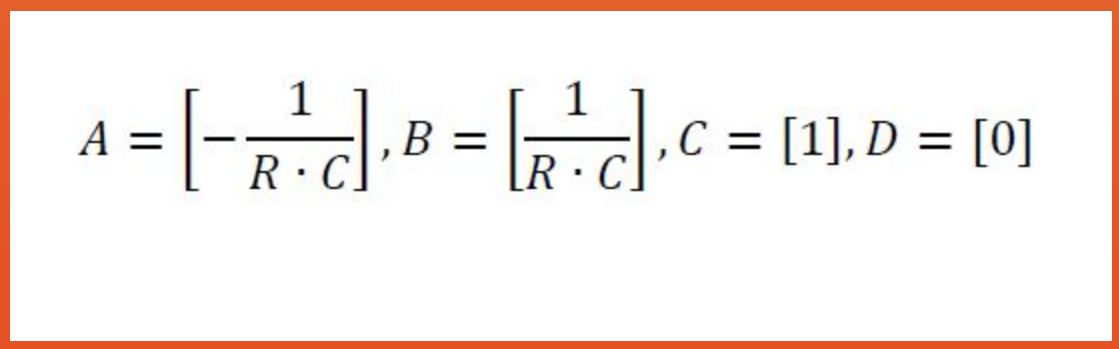

Assume the DC gain is K


$$G(s)=\frac{K}{1+\frac{s}{\omega_0}}$$



$$G(j\omega)=\frac{K}{1+\frac{j\omega}{\omega_0}}$$



$$\omega << \omega_0, 
1+\frac{j\omega}{\omega_0} =1, |G(j\omega)|=K$$



$$\omega =\omega_0, 
1+\frac{j\omega}{\omega_0} =1+j, |G(j\omega)|=|\frac{K}{1+j}|=\frac{K}{\sqrt{2}}$$



$$\omega >> \omega_0, 
1+\frac{j\omega}{\omega_0} =\inf, |G(j\omega)|=0$$


R = 1 kΩ and C = 1 µF

R = 1000;
C = 1/10^6;
fc = 1/(2*pi*R*C) % Hz

fc = 159.1549

num = 1/(R*C);
den = [1 1/(R*C)];
sys = tf(num,den)

sys =
 
    1000
  --------
  s + 1000
 
Continuous-time transfer function.



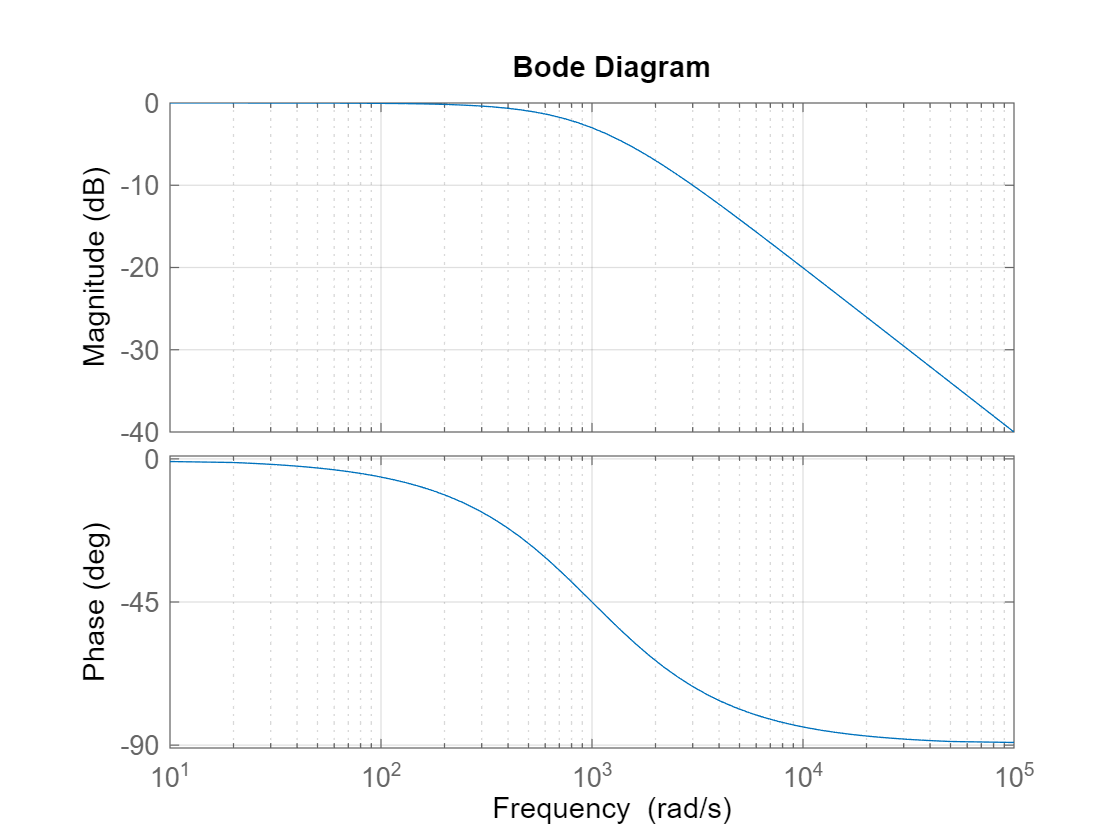

bode(sys)
grid on

input signal: sinuoidal 5 V and a frequency of 1 kHz.

V_in(t) = 2.5 sin(2π1000t) + 2.5 sin(2π2000t)

f_in = 1000;
w_in = 2*pi*f_in;
V_out = 2.5*sin(2*pi*1000*t) + 2.5*sin(2*pi*2000*t);

[A,B,C,D] = tf2ss(num,den);
sys_c_ss = ss(A,B,C,D);
sys_d = c2d(sys_c_ss,0.1);
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
t = 0:0.1:100;
u = 2.5*sin(2*pi*1000*t) + 2.5*sin(2*pi*2000*t);
% xp = sys_d.A*x+B*u;
% y = C*xp;